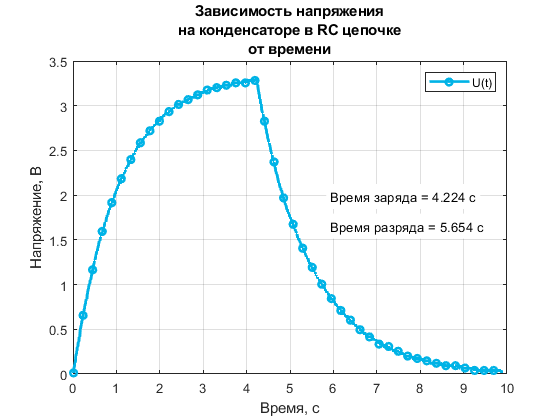

data = importdata("data.txt")';
scale = importdata("scale.txt")';

dV = scale(1);
dt = scale(2);

U = data * dV;
t = (1:length(data)) * dt;

[m, i] = max(data);

tCharge = i * dt;
tDischarge = (length(data) - i) * dt;

f1 = figure('Name','Иван Потылицын, группа 733','NumberTitle','off');
plot(t, U, '-o', 'Color', [0,0.7,0.9], 'MarkerIndices',1:20:length(U), 'LineWidth', 2, 'MarkerSize', 5);
grid on;
title({'Зависимость напряжения', 'на конденсаторе в RC цепочке', 'от времени'});
xlabel("Время, с");
ylabel("Напряжение, В");
legend('U(t)', 'Location', 'northeast');

text(max(t) * 0.6, max(U) * 0.6, ['Время заряда = ' num2str(tCharge) ' c'], 'BackgroundColor', 'w');
text(max(t) * 0.6, max(U) * 0.5, ['Время разряда = ' num2str(tDischarge) ' c'], 'BackgroundColor', 'w');
set(gcf,'Visible','on');

saveas(f1, "cap.png");
saveas(f1, "cap.svg");